# Razionale.

**Obiettivo della tesina**:

- Infarinatura di come è possible descrivere un sistema matematico/fisico.

- Simulazione.

- Controllo

- ecc.

# 1) Cruise Control.

#### Cos'è il Cruise Control.

Il cruise control, o regolatore di velocità, è un sistema elettronico che consente ad un veicolo di mantenere una velocità costante impostata dal conducente, senza la necessità di agire costantemente sull'acceleratore.

Principio di Funzionamento:

- **Impostazione della Velocità: **Il conducente imposta la velocità da mantenere tramite pulsante o leva e il sistema memorizza questa velocità come valore di riferimento.

- **Controllo della Velocità: **l'unità di controllo elettronico (ECU) monitora costantemente la velocità del veicolo tramite sensori (ad esempio, sensore di velocità delle ruote). L'ECU confronta la velocità misurata con quella impostata: se è minore, l'ECU va ad agire sull'accelerazione per aumentarne la velocità, in caso contrario si diminuisce l'accelerazione o si agisce sui freni.

- **Attuazione:** nel caso di motori a combustione, l'ECU agisce sull'acceleratore controllando elettronicamente l'iniezione del carburante e/o i freni, mentre per i motori elettrici si va ad agire direttamente sulla coppia (e quindi corrente). Per quest'ultimi la gestione della decelerazione può essere gestita più facilmente sfruttando la frenata rigenerativa.

- **Disattivazione: **Il cruise control si disattiva automaticamente quando si preme il pedale del freno o anche tramite pulsante dedicato.

# 2) Analisi del modello Fisico.

### Descrizione del modello Fisico

Il cruise control è un sistema a retroazione con lo scopo di controllare la velocità di crociera e mantenere costante la velocità del veicolo nonostante i disturbi esterni, come le variazioni del vento o della pendenza della strada. Ciò avviene misurando la velocità del veicolo, confrontandola con la velocità di riferimento e regolando automaticamente l'acceleratore in base a una legge di controllo.

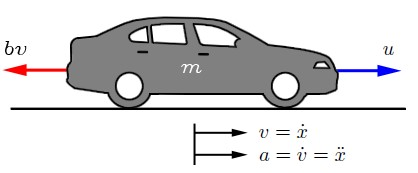

Si considera un semplice modello della dinamica del veicolo, mostrato nel diagramma a corpo libero (immagine sopra). Sul veicolo, di massa **m**, agisce una forza di controllo, **u**. La forza** u** rappresenta la forza generata all'interfaccia strada/pneumatico. In questo caso si assume di poter controllare direttamente questa forza trascurando l'attrito dei pneumatici, della pendenza della strada ecc. che contribuiscono a generare le forze resistive. Per questo modello si considera l'attrito viscoso **bv **(resistenza dell'aria) ipotizzando che vari linearmente con la velocità del veicolo **v** e che agisca in direzione opposta al moto.

### **Equazione del modello Fisico **[Cruise Control: System Modeling](https://ctms.engin.umich.edu/CTMS/index.php?example=CruiseControl&section=SystemModeling).

Sommando le forze nella direzione x e applicando la seconda legge di Newton, si ottiene la seguente equazione del sistema:

#### 
$$\sum m\dot{v} =u-bv\to m\dot{v} +bv=u\;$$


Che è un'equazione del primo ordine, Lineare Tempo Invariante (LTI) --> **Descrivere meglio equazioni LTI. **

Dal momento che si è interessati a controllare la velocità del veicolo, l'equazione di uscita può essere scritta come:

#### 
$$y=v$$


### **Descrizione del modello fisico con Equazioni di Spazio di Stato **[System Modeling](https://ctms.engin.umich.edu/CTMS/index.php?example=Introduction&section=SystemModeling).

Per i sistemi continui lineari tempo-invarianti (LTI), la rappresentazione standard dello spazio di stato è data da:

#### 
$$\begin{array}{l}
\dot{\mathbf{x}} =A\mathbf{x}+B\mathbf{u}\\
\mathbf{y}=C\mathbf{x}+D\mathbf{u}
\end{array}$$


# Analisi del sistema.

#### **Stabilità del sistema**:

- Verifica/Dimostrazione della Stabilità del sistema a catena aperta: [Cruise Control: Root Locus Controller Design](https://ctms.engin.umich.edu/CTMS/index.php?example=CruiseControl&section=ControlRootLocus).

- Risposta a segnali canonici a catena aperta: [Cruise Control: System Analysis](https://ctms.engin.umich.edu/CTMS/index.php?example=CruiseControl&section=SystemAnalysis).

**Prestazioni a catena aperta**:

- Modello Sistema a catena aperta.

- Prestazioni SIstema con segnale canonico a catena aperta.

**Prestazioni a catena chiusa**:

- Sintesi del controllore dal punto di vista teorico (vedere foglio con calcoli fatti a mano).

- Specifiche di prestazione: [Cruise Control: Root Locus Controller Design](https://ctms.engin.umich.edu/CTMS/index.php?example=CruiseControl&section=ControlRootLocus).

- Specifiche di prestazione per valore a regime: [Introduction: System Analysis](https://ctms.engin.umich.edu/CTMS/index.php?example=Introduction&section=SystemAnalysis#8).

- Video Control Tutorials: [ Control Specifications and PID Control](https://www.youtube.com/watch?v=RYWPqb2hAEM).

- Lezioni dispense 40/42 - 50/56.

- Specificare errore nullo a regime per sistemi del primo ordine (dispense 38 e 47).

Teorema del valore finale:

non `e possibile applicare questo teorema ”bendati”, cio`e calcolare il valore finale senza prima controllare se il sistema `e stabile. Se il sistema `e stabile il teorema `e applicabile e il limite restituisce un valore sensato. 

Se ci troviamo nel secondo e nel terzo quadrante del piano cartesiano significa cheabbiamo poli con parte reale Re < 0: questo significa che il sistema `e stabile ed eventualmente tender`a a zero.